# ME 535 Assignment 5 - Fall 2018

# Debabrata Auddya

**Question 5.5: ** Plot the cubic B-spline curve defined with the control points. Evaluate it at u = 1.5

**Ans: **

The Knot vector is : {0 0 0 1 2 3 4 5 6 6 6}

Points are: 


$$P_0 = (10, 15, 20) \\
P_1 = (20, 25, 5) \\
P_2 = (40, 25, 0) \\
P_3 = (60, 5, 0) \\
P_4 = (80, 15, -5) \\
P_5 = (80, 30, -10) \\
P_6 = (90, 45, -10) \\
P_7 = (115, 40, -5) \\
P_8 = (125, 15, 0)$$


%define control points
%P=[0 0; 1 2; 3 5; 5 0; 7 -1];
%define order
%define knot vector
%knots = [0 0 0 0 0.5 1 1 1 1];
%u=0.2;
%L=4; % u=0.2 is between u4=0 and u5=0.5

% P=[0 0;1 0;2 0;4 1;5 2;8 2;9 3];
% order = 4;
% knots=[0 0 0 0 .25 .5 .75 1 1 1 1];
% u=0.6;
% L= 6;

P=[10,15,20; 20,25,5; 40,25,0; 60,5,0; 80,15,-5;
    80,30,-10; 90,45,-10; 115,40,-5; 125,15,0];
order = 4;
knots = [0 0 0 1 2 3 4 5 6 6 6];
u = 1.5

u = 1.5000

%L = 5;
L = findspan(size(P,1),order-1,u,knots)

L = 4

disp("Value of the curve at u=1.5")

Value of the curve at u=1.5


Q = deBoor (order, knots, P, u, L)

Q =    30.1042   24.2708    2.9688


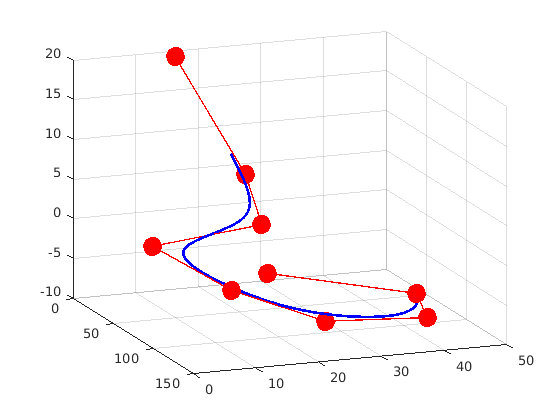


%define display configuration
n = 40;
%do calculation
Q = bsplineCurve(P, order, knots, n);
%do plot of control polygon
plot3(P(:,1),P(:,2),P(:,3),'r-o', 'linewidth',1,'MarkerFaceColor', 'r', 'MarkerSize',14);
hold on;
%do plot of b-spline curve
plot3(Q(:,1),Q(:,2),Q(:,3),'-b', 'linewidth',2);
grid on
hold off

view([68.9 18.8])

**Question 5.6: Blossom for B Splines**

P=[0, 0; 1, 0; 1, 1; 0, 1; 0, 2; 2, 2];
order = 4;
knots = [-2 -2 -1 0 2 4 5 6 6 6];
u = 3

u = 3

%L = 5;
L = findspan(size(P,1),order-1,u,knots)

L = 5


Q = deBoor(order, knots, P, u, L)

Q =     0.4083    1.0167




%define display configuration
n = 40;
%do calculation
Q = bsplineCurve(P, order, knots, n);
%do plot of control polygon
plot(P(:,1),P(:,2),'r-o', 'linewidth',1,'MarkerFaceColor', 'r', 'MarkerSize',14);
hold on;
%do plot of b-spline curve
plot(Q(:,1),Q(:,2),'-b', 'linewidth',2);
hold on

**Question 5.6(d): Bezier extraction and original curve**

**Obtain the Bézier representation of the curve segment for knot interval [2, 4]. Draw the original curve and the new Bézier curve and their control points on the same plot. **

**(**Extracted Bezier shown as green segment**)**

n = 100;
disp("Control Points of Extracted Bezier")

Control Points of Extracted Bezier


P1 = [0.8 0.8;0.6 1;0.2 1;0.06 1.33]

P1 =     0.8000    0.8000
    0.6000    1.0000
    0.2000    1.0000
    0.0600    1.3300


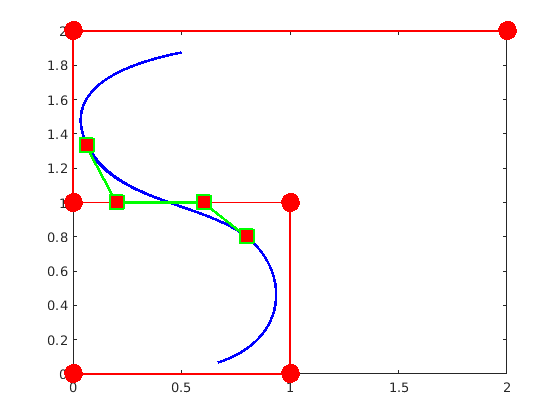

Q = bezierCurve(P1, n);
bezierCurvePlot(P1, Q, '-gs','b');

**Question 5.7**: NURBS curve evaluation

Value of the curve at c(1.25) = (-0.36809,0.9297), Detailed solution attached at the end of this script. 

clear all
close all
P=[1, 0; 1, 1; 0, 1; -1, 1; -1, 0];
P_w = [1, 0, 1; 0.7071, 0.7071, 0.7071; 0, 1, 1; -0.7071, 0.7071, 0.7071; -1, 0, 1];
order = 3;
knots = [0 0 0 1 1 2 2 2];
u = 1.25

u = 1.2500

%L = 5;
L_w = findspan(size(P_w,1),order-1,u,knots)

L_w = 5


Q_w = deBoor(order, knots, P_w, u, L_w)

Q_w =    -0.3277    0.8277    0.8902


disp('The value of the curve at c=1.25 is')

The value of the curve at c=1.25 is


Q = Q_w(:,:)/Q_w(:,3)

Q =    -0.3681    0.9298    1.0000


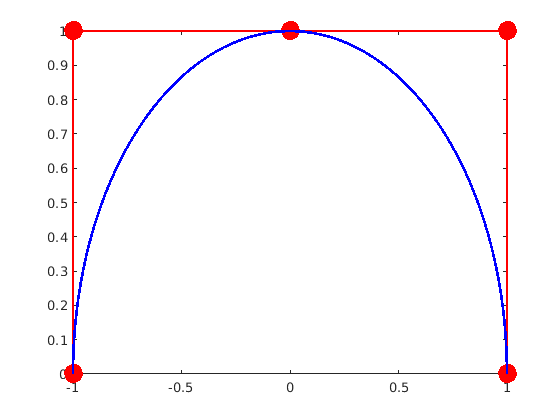


n = 40;
%do calculation
Qw = bsplineCurve(P_w, order, knots, n);
p =size(Qw,1);

Q = zeros(p,2);
for i=1:p
    Q(i,1) = Qw(i,1)/Qw(i,3);
    Q(i,2) = Qw(i,2)/Qw(i,3); 
end 
%do plot of control polygon
plot(P(:,1),P(:,2),'r-o', 'linewidth',1,'MarkerFaceColor', 'r', 'MarkerSize',14);
hold on;
%do plot of b-spline curve
plot(Q(:,1),Q(:,2),'-b', 'linewidth',2);
hold off

* Additional functions implemented:*

**deBoor Algorithm**

function [R] = deBoor(k, t, P, u, L)
%k order of b-spline
%t knot vector
%P control points with format that every row is a point
%u parameter value 
%L  index of knot such as t(L) <= u < t(L+1)

for j=1:k
    A(j,:) = P(L-k+j,:);  %the control points that affect the computation of point on curve
end

for r=1:(k-1)   %time to do recursive compuation
    for j=(k):(-1):(r+1)   %do one time computation to get next level control points 
        i = L-k+j;         
        d1 = u - t(i);       %for left term in recursive format
        d2 = t(i+k-r) - u;   %for right term in recursive format
        A(j,:) = (d1*A(j,:) + d2*A(j-1,:))/(d1 + d2);  %carry out computation
    end
end
R = A(k,:);  %return the computed point value
end

**finding Knot Span**

%%% =================== find knot span =================
% U: knots
% n: number of CP minus 1; that is, p0, p1, ..., p_n
% p: degree
% u: u value
% return the span, starting from u_0. 
% Date: Oct 14, 2018
function s = findspan(n,p,u,U)
if u < U(p) || u > U(n+p-1)
    print "error in u value wrt knots"
    u
    U
    return;
end
if (u==U(n+p-1))  % XQ 
    s=n; 
    return,  
end
low = p;
high = n + 1;
mid = floor((low + high) / 2);
while (u < U(mid+1) || u >= U(mid+2))
    if (u < U(mid+1))
        high = mid;
    else
        low = mid;
    end
    mid = floor((low + high) / 2);
end
s = mid;

s= s+1; % XQ. For Matlab, we should add one to the return value.
end

**bSplineCurve**

function [Q] = bsplineCurve(P, k, t, n)
%P control points of b-spline
%k order of b-spline
%t knot vector of b-spline
%n for display, namely how many points to be computed on every segment

[m,d] = size(P);   %get number of control points m
L = 1;             %index to computed point

for i=(k):(m)       %b-splinbe parameter domain  is t(k) - t(m+1)
    step = (t(i+1)-t(i))/(n-1);   %parameter increment step
    for u=t(i):step:(t(i+1))      %do calculation for every segment
        Q(L,:) = deBoor(k, t, P, u, i); %P, degree, u, knots, i, 0);
        L = L+1;
    end
end
end

**Functions for BSpline**

function bezierCurvePlot(P, Q, sP, sQ)
% plot the given control points P and points Q on beizer curve
% P control points
% Q points on bezier curve
% style for P and style for Q: sP, sQ

dim = length(P(1,:));
if dim == 2;
    plot(Q(:,1),Q(:,2),sQ, 'linewidth',2);
    hold on;
    plot(P(:,1),P(:,2),sP, 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',14);
    %hold off;
else 
    if dim == 3    
        plot(P(:,1),P(:,2),sP, 'linewidth',2);
        hold on;
        plot(Q(:,1),Q(:,2),sQ, 'linewidth',2);
        %hold off;
    end
end
end
function [Q] = deCasteljau(P, u)
% computer point with parameter value u on bezier curve defined by control points P
% P control points, in matrix format: {size of P} * {dimension of P}
% dimension of P is 2 or 3
% u parameter with value [0 1]
% Q point lying on the bezier curve

% input: P: control points P; u:  parameter value 
% output: Q: the Bezier curve point at u

% example: >> P = [0 0; 1 2; 3 5; 4,4; 5 0];
% >> Q=deCasteljau(P, 0.5)
% output:Q =
%   2.6875    3.3750

% m: # of control points; m = the degree of the curve +1
[m, n] = size(P);  
if m <= 1 
    err('please specify at least 2 control points');
end

if u < 0 | u > 1
    err('u must be in range from 0 to 1');
end

d = m-1; % degree

for r=1:d
    for i=1:(d+1-r) % the array index in Matlab starts with 1, not 0.
        P(i,:) = (1-u)*P(i,:) + u*P(i+1,:); 
        % ':' operator on all columns: x, y, z
    end
end
Q=P(1,:);
end
function [Q] = bezierCurve(P, n)
% computer points on bezier curve defined by control points P
% P control points, in matrix format: {size of P} * {dimension of P}
% n the number of points need to be computed
% isPlot  1 for plot, 0 for non plot
% Q points lying on the bezier curve
i = 1;
for u=0:(1/(n-1)):1
    Q(i,:) = deCasteljau(P, u);
    i = i + 1;
end
end